# Experiment object creation for analysis

#### Creat aud_ephys experiment object (Including all unprocessed data: Pathways, input channels, facemap whisking analysis, running, mic, spk, sorted spikes and metadata, condition ephocs, evoked events, aligned cam frames)

Choose parameters file for exp

cd /home/ben/Z/Parameters_files/FVB/ % optional 
[file,path] = uigetfile('*.m');
cd(path)
%run(file)

Create an initial object

experiment = auditory_ephys_exp(file)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: []
              Conditions: []
                    Cams: []
                      SF: 30000
                   color: [1×1 struct]
            sound_events: []
         predictionModel: []
                   PSTHs: []
                   sound: []
                 running: []
            evokedEvents: []
         conditionVector: []
                Whisking: []
               timeStamp: []


Choose which additional data to add to the experiment object based on the type of experiment (comment and uncomment as necessery)

% Condition times
experiment.Conditions = experiment.getConditionsTimes

% Units
experiment.Units = sorted_from_phy(experiment.Pathways.sorting)

% cameras sync
% whisking camera sync
experiment.Cams.whisking = experiment.syncCamera(1)
% face camera sync
% experiment.Cams.whisking = experiment.syncCamera(2)

% evoked events based on speaker data
experiment.evokedEvents = experiment.getEvoked

Analog data channels

cd([experiment.Pathways.exp,'/experiment1/recording1'])
data = load_open_ephys_binary('structure.oebin','continuous',1,'mmap');
experiment.sound = data.Data.Data.mapped(32+experiment.analog_channels.mic,:)
experiment.running = encoder2speed(data.Data.Data.mapped(32+experiment.analog_channels.encoder,:),0.065);
clear data

Varify conditions channels and what ever

figure; plot([1:length(experiment.sound)]/30000,experiment.sound)
for con = 1: length(experiment.Conditions.all_changes)
    xline(experiment.Conditions.all_changes(con)/30000)
end

conditionDiff = diff(experiment.Conditions.all_changes)/30000

## Processes data

Identify whisking epochs and divided into two types

Load whisking vector, and chossing the appropriate one for analysis

cd(experiment.Pathways.main)
[file,path] = uigetfile('*.mat');
load([path,file],'motion_1','motSVD_1');

figure;plot(motion_1)

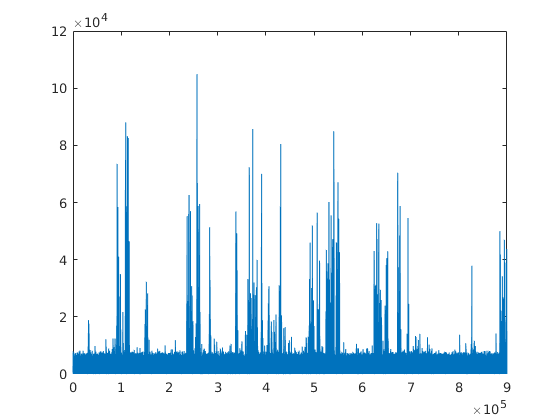

figure; plot(abs(motSVD_1(:,8)))

whiskingData = motSVD_1(:,8);

whiskingData = wdenoise(double(whiskingData),10)

figure; plot(whiskingData)

clear motSVD_1 motion_1


figure; plot(whiskingData)

Filter and smooth data to identify threshold

[b,a] = butter(3,[10,50]/200,'bandpass')

b =     0.0181         0   -0.0543         0    0.0543         0   -0.0181


a =     1.0000   -4.4595    8.5210   -8.9851    5.5363   -1.8897    0.2781


whisking_filtered = filtfilt(b,a,double(whiskingData))

whisking_filtered = 	1.0e+04 *

    0.0166
    0.0323
    0.0631
    0.1180
    0.1933
    0.2674
    0.3039
    0.2680
    0.1491
   -0.0228


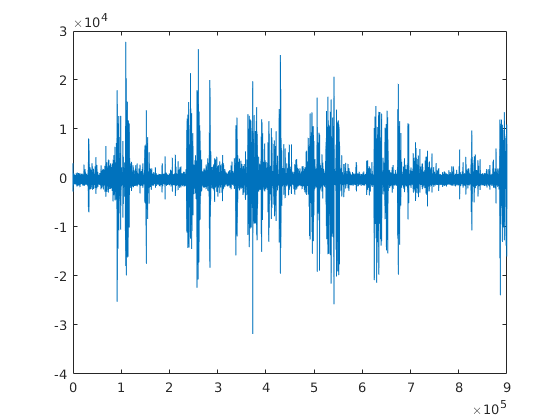

figure; plot(whisking_filtered)

whisking_smoothed = smoothdata(abs(whisking_filtered),"movmean","SmoothingFactor",0.5)

whisking_smoothed = 	1.0e+03 *

    1.0651
    1.0784
    1.1042
    1.1267
    1.1321
    1.1109
    1.0919
    1.1016
    1.1285
    1.1585


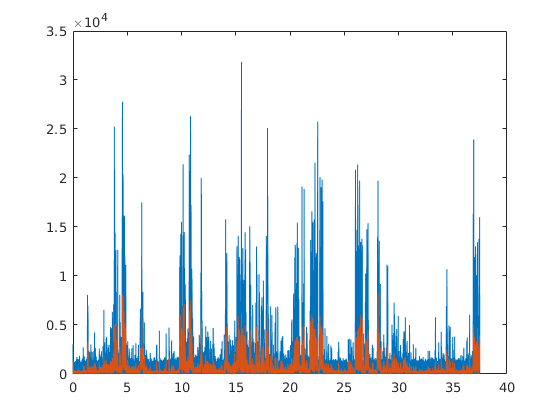

figure;
plot([1:length(whisking_filtered)]/400/60,abs(whisking_filtered))
hold on
plot([1:length(whisking_filtered)]/400/60,whisking_smoothed)

Identify whisking epochs

all_above = find(whisking_smoothed > 800)

all_above =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


all_below = find(whisking_smoothed < 800)

all_below =     35
    36
    37
    38
    39
    40
    41
    42
    43
    44


start_epoch = intersect(all_above,all_below+1)

start_epoch =        24827
       24830
       31742
       31797
       32421
       32749
       32914
       33342
       33561
       33573



endEpoch = intersect(all_above,all_below-1)

endEpoch =           34
       24827
       24834
       31785
       32417
       32742
       32821
       33284
       33486
       33569


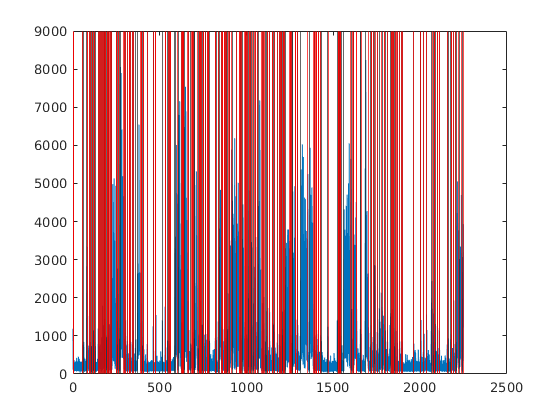

figure
plot([1:length(whisking_filtered)]/400,whisking_smoothed)
xline(start_epoch/400)
xline(endEpoch/400,'r')

if endEpoch(1) < start_epoch(1)
    endEpoch(1) = []
end

endEpoch =        24827
       24834
       31785
       32417
       32742
       32821
       33284
       33486
       33569
       33574


jj = endEpoch - start_epoch(2:end);

 jjk = jj > -600

jjk = 1438×1 logical array
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1


 endEpoch(jjk) = []

endEpoch =        24834
       33579
       40127
       45869
       47522
       49587
       58477
       66125
       68241
       70562


 start_epoch([false;jjk]) = []

start_epoch =        24827
       31742
       40104
       45668
       47477
       49553
       58109
       66106
       68183
       69411


if length(start_epoch) > length(endEpoch)
    endEpoch = [endEpoch;length(whisking_smoothed)]
end

endEpoch =        24834
       33579
       40127
       45869
       47522
       49587
       58477
       66125
       68241
       70562


divide epochs to short epochs and long continuous whisking

epochLength = endEpoch-start_epoch

epochLength =            7
        1837
          23
         201
          45
          34
         368
          19
          58
        1151


extremeShortEpochs = epochLength < 20

extremeShortEpochs = 177×1 logical array
   1
   0
   0
   0
   0
   0
   0
   1
   0
   0


start_epoch(extremeShortEpochs) = [];
endEpoch(extremeShortEpochs) = [];
epochLength(extremeShortEpochs) = [];

longEpoch(:,1) = start_epoch(epochLength > 2000)

longEpoch =        89756       96752
       97452       99647
      108645      117586
      148637      155344
      235559      240959
      242411      249014
      256937      264745
      281025      286090
      336988      341953
      361728      366329


longEpoch(:,2) = endEpoch(epochLength > 2000)

longEpoch =        89756       96752
       97452       99647
      108645      117586
      148637      155344
      235559      240959
      242411      249014
      256937      264745
      281025      286090
      336988      341953
      361728      366329


shortEpoch(:,1) = start_epoch(epochLength <= 2000)

shortEpoch =        31742
       40104
       45668
       47477
       49553
       58109
       68183
       69411
       73144
       75318


shortEpoch(:,2) = endEpoch(epochLength <= 2000)

shortEpoch =        31742       33579
       40104       40127
       45668       45869
       47477       47522
       49553       49587
       58109       58477
       68183       68241
       69411       70562
       73144       74267
       75318       75406


varify epochs

figure
plot([1:length(whisking_filtered)]/400,whisking_smoothed)
hold on
y = [0 0 9000 9000]

y =            0           0        8000        8000


for i = 1:length(longEpoch)
    x = [longEpoch(i,1)/400,longEpoch(i,2)/400,longEpoch(i,2)/400,longEpoch(i,1)/400]
    fill(x,y,'r','FaceAlpha',0.3)
end

x =        89756       96752       96752       89756


x =        97452       99647       99647       97452


x =       108645      117586      117586      108645


x =       148637      155344      155344      148637


x =       235559      240959      240959      235559


x =       242411      249014      249014      242411


x =       256937      264745      264745      256937


x =       281025      286090      286090      281025


x =       336988      341953      341953      336988


x =       361728      366329      366329      361728


x =       367242      376239      376239      367242


x =       377370      383100      383100      377370


x =       389600      394832      394832      389600


x =       403501      407337      407337      403501


x =       410754      413187      413187      410754


x =       416020      418512      418512      416020


x =       419521      422129      422129      419521


x =       427188      433330      433330      427188


x =       489542      499958      499958      489542


x =       506249      512505      512505      506249


x =       524493      541712      541712      524493


x =       545128      553464      553464      545128


x =       608956      611065      611065      608956


x =       624142      640284      640284      624142


x =       646375      654103      654103      646375


x =       673010      681471      681471      673010


x =       693902      696281      696281      693902


x =       705081      708312      708312      705081


x =       709251      712100      712100      709251


x =       714633      716851      716851      714633


x =       730484      733664      733664      730484


x =       825272      828612      828612      825272


x =       884198      888940      888940      884198


x =       889897      896073      896073      889897


x =       897626      899831      899831      897626


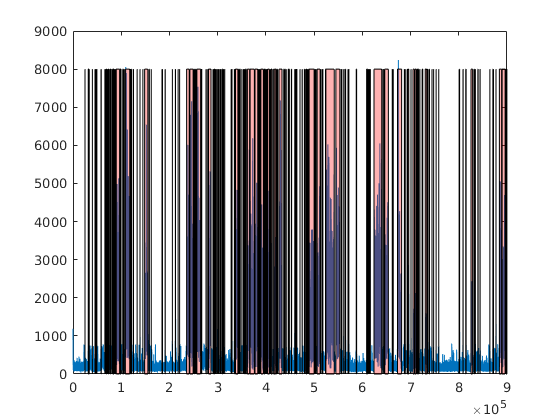

x =        24827       24834       24834       24827


x =        31742       33579       33579       31742


x =        40104       40127       40127       40104


x =        45668       45869       45869       45668


x =        47477       47522       47522       47477


x =        49553       49587       49587       49553


x =        58109       58477       58477       58109


x =        66106       66125       66125       66106


x =        68183       68241       68241       68183


x =        69411       70562       70562       69411


x =        71830       71845       71845       71830


x =        73144       74267       74267       73144


x =        75318       75406       75406       75318


x =        77735       78769       78769       77735


x = 1×4
       81477       81952       81952       81477


x = 1×4
       82975       84899       84899       82975


x = 1×4
       85817       85836       85836       85817


x = 1×4
       87189       87702       87702       87189


x = 1×4
       88675       88706       88706       88675


x = 1×4
      103215      104710      104710      103215


x = 1×4
      106993      107031      107031      106993


x = 1×4
      119611      119725      119725      119611


x = 1×4
      121136      121683      121683      121136


x = 1×4
      125088      125410      125410      125088


x = 1×4
      132994      133009      133009      132994


x = 1×4
      139003      139041      139041      139003


x = 1×4
      144818      144843      144843      144818


x = 1×4
      157767      158421      158421      157767


x = 1×4
      162334      162344      162344      162334


x = 1×4
      184589      184647      184647      184589


x = 1×4
      185451      185485      185485      185451


x = 1×4
      190969      191200      191200      190969


x = 1×4
      206004      206083      206083      206004


x = 1×4
      212243      212672      212672      212243


x = 1×4
      218016      218042      218042      218016


x = 1×4
      221000      221018      221018      221000


x = 1×4
      250775      250990      250990      250775


x = 1×4
      252454      253265      253265      252454


x = 1×4
      254055      254352      254352      254055


x = 1×4
      255231      255579      255579      255231


x = 1×4
      266817      266916      266916      266817


x = 1×4
      275867      276238      276238      275867


x = 1×4
      279363      279405      279405      279363


x = 1×4
      290315      290801      290801      290315


x = 1×4
      291649      291674      291674      291649


x = 1×4
      293014      293858      293858      293014


x = 1×4
      295673      295726      295726      295673


x = 1×4
      298165      298219      298219      298165


x = 1×4
      300312      300423      300423      300312


x = 1×4
      301617      301641      301641      301617


x = 1×4
      304344      304383      304383      304344


x = 1×4
      306400      306420      306420      306400


x = 1×4
      309082      310285      310285      309082


x = 1×4
      311456      311509      311509      311456


x = 1×4
      312320      312376      312376      312320


x = 1×4
      314606      314644      314644      314606


x = 1×4
      327927      327958      327958      327927


x = 1×4
      329832      329850      329850      329832


x = 1×4
      334567      334973      334973      334567


x = 1×4
      343097      343152      343152      343097


x = 1×4
      343978      344224      344224      343978


x = 1×4
      345166      345423      345423      345166


x = 1×4
      348130      348526      348526      348130


x = 1×4
      352629      352671      352671      352629


x = 1×4
      354517      355086      355086      354517


x = 1×4
      357101      358033      358033      357101


x = 1×4
      360211      360947      360947      360211


x = 1×4
      384818      384938      384938      384818


x = 1×4
      386455      386513      386513      386455


x = 1×4
      387389      387651      387651      387389


x = 1×4
      396418      396748      396748      396418


x = 1×4
      397419      398376      398376      397419


x = 1×4
      399992      400422      400422      399992


x = 1×4
      402366      402387      402387      402366


x = 1×4
      408123      408160      408160      408123


x = 1×4
      409219      409408      409408      409219


x = 1×4
      424068      424359      424359      424068


x = 1×4
      437071      437567      437567      437071


x = 1×4
      439493      440372      440372      439493


x = 1×4
      443178      443195      443195      443178


x = 1×4
      446968      447844      447844      446968


x = 1×4
      448574      448636      448636      448574


x = 1×4
      452979      453297      453297      452979


x = 1×4
      459728      460039      460039      459728


x = 1×4
      462166      462297      462297      462166


x = 1×4
      463818      464287      464287      463818


x = 1×4
      470699      470701      470701      470699


x = 1×4
      475146      475395      475395      475146


x = 1×4
      479855      479924      479924      479855


x = 1×4
      480834      481026      481026      480834


x = 1×4
      483497      484837      484837      483497


x = 1×4
      485652      485659      485659      485652


x = 1×4
      487862      488131      488131      487862


x = 1×4
      501323      502157      502157      501323


x = 1×4
      503916      503918      503918      503916


x = 1×4
      513500      513549      513549      513500


x = 1×4
      516357      516460      516460      516357


x = 1×4
      517826      518146      518146      517826


x = 1×4
      523735      523769      523769      523735


x = 1×4
      556278      556302      556302      556278


x = 1×4
      557406      557450      557450      557406


x = 1×4
      561378      561518      561518      561378


x = 1×4
      562164      562192      562192      562164


x = 1×4
      565169      565482      565482      565169


x = 1×4
      570376      570414      570414      570376


x = 1×4
      572182      572196      572196      572182


x = 1×4
      587350      588129      588129      587350


x = 1×4
      612637      612638      612638      612637


x = 1×4
      613533      613547      613547      613533


x = 1×4
      614494      614547      614547      614494


x = 1×4
      616657      616706      616706      616657


x = 1×4
      642754      642994      642994      642754


x = 1×4
      645420      645444      645444      645420


x = 1×4
      662070      662118      662118      662070


x = 1×4
      663552      664070      664070      663552


x = 1×4
      687117      687522      687522      687117


x = 1×4
      688650      689108      689108      688650


x = 1×4
      692933      692946      692946      692933


x = 1×4
      700832      701014      701014      700832


x = 1×4
      713826      714027      714027      713826


x = 1×4
      719391      719440      719440      719391


x = 1×4
      724038      725180      725180      724038


x = 1×4
      734309      734329      734329      734309


x = 1×4
      735029      735672      735672      735029


x = 1×4
      738405      739182      739182      738405


x = 1×4
      744375      744423      744423      744375


x = 1×4
      747750      747755      747755      747750


x = 1×4
      752943      752962      752962      752943


x = 1×4
      758513      758528      758528      758513


x = 1×4
      800710      800729      800729      800710


x = 1×4
      801477      801872      801872      801477


x = 1×4
      808877      808958      808958      808877


x = 1×4
      814496      815297      815297      814496


x = 1×4
      831567      832369      832369      831567


x = 1×4
      833425      833514      833514      833425


x = 1×4
      834406      834458      834458      834406


x = 1×4
      839655      839998      839998      839655


x = 1×4
      844135      844190      844190      844135


x = 1×4
      864457      864501      864501      864457


x = 1×4
      870620      871060      871060      870620


x = 1×4
      871881      872038      872038      871881


x = 1×4
      877102      877290      877290      877102


for i = 1:length(shortEpoch)
    x = [shortEpoch(i,1)/400,shortEpoch(i,2)/400,shortEpoch(i,2)/400,shortEpoch(i,1)/400]
    fill(x,y,'b','FaceAlpha',0.3)
end

Identify sound events (Only when sound is clean enough through all conditions)

Annotate for which analysis this experiment can be used (sound events, continuous whisking, discrete whisking, no whisking periods)

#### save object